TRKS = {
  'doubpend_td40_norot.trk' 'td40_nr' 40 0
  'doubpend_td40_rot.trk' 'td40_r' 40 1
  'doubpend_td80_norot.trk' 'td80_nr' 80 0 
  'doubpend_td80_rot.trk' 'td80_r' 80 1
  'doubpend_td120_norot.trk' 'td120_nr' 120 0 
  'doubpend_td120_rot.trk' 'td120_r' 120 1
  'doubpend_td160_norot.trk' 'td160_nr' 160 0 
  'doubpend_td160_rot.trk' 'td160_r' 160 1
  };
NTRKS = size(TRKS,1);
LBL = 'dp_1205_more.lbl';

lbl = load(LBL,'-mat');
trks = cellfun(@(x)load(x,'-mat'),TRKS(:,1));

npts = Labeler.labelPosNPtsLbled(lbl.labeledpos{1});
frms4 = find(npts==4);
nfrms4 = numel(frms4);

292 frames with all 4 pts lbled.


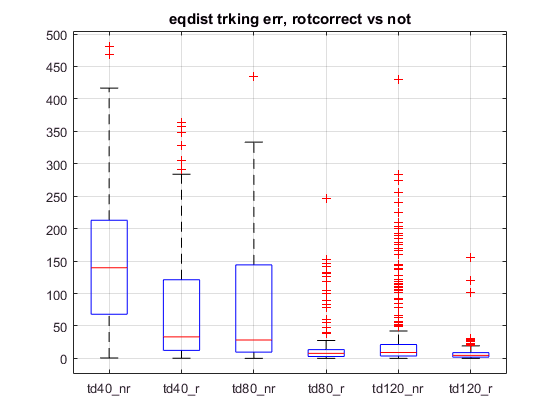

fprintf('%d frames with all 4 pts lbled.\n',nfrms4);

lposf4 = lbl.labeledpos{1}(:,:,frms4);
dmat = nan(nfrms4,4,NTRKS);
for iTrk=1:NTRKS
  trkf4 = trks(iTrk).pTrk(:,:,frms4);
  d = squeeze(sqrt(sum((trkf4-lposf4).^2,2)))';
  dmat(:,:,iTrk) = d;
end

figure;
dmatPt4 = squeeze(dmat(:,4,:));
g = TRKS(:,2)';
boxplot(dmatPt4,g)
grid on

title('eqdist trking err, rotcorrect vs not','fontweight','bold');

dmatmu = squeeze(mean(dmat,1));
dmatmu = dmatmu'; % rows: iTrk. cols: iPt
format short

dmatmu =    18.6659   27.6511   54.3573  148.5264
    4.2687    8.3995   15.9027   74.2309
    6.9763    9.1716   17.0687   79.2454
    0.3846    2.4358    4.0408   14.7246
    3.7429    5.1368    9.2895   33.0933
    0.3802    2.0677    3.2281    7.5066

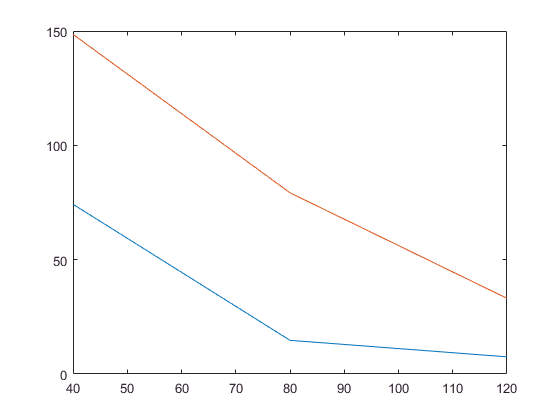

dmatmu

figure;
tdfrms = cell2mat(TRKS(:,3));
rotflag = cell2mat(TRKS(:,4));
dmatmuPt4Rot = dmatmu(rotflag==1,4);
dmatmuPt4NR = dmatmu(rotflag==0,4);
frmsRot = tdfrms(rotflag==1);
frmsNR = tdfrms(rotflag==0);

plot(frmsRot,dmatmuPt4Rot,'.-',frmsNR,dmatmuPt4NR,'.-');
grid on;
xlabel('num training frames','fontweight','bold');
ylabel('mean tracking err, pt 4 (px)','fontweight','bold');
legend('rot correct','no correct');
axis([0 200 0 200]);
title('Double pendulum, rot correction','fontweight','bold');
